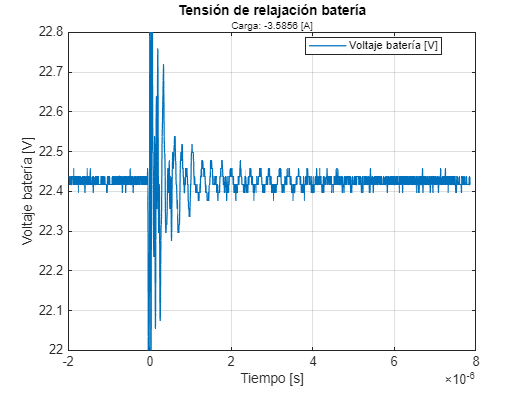

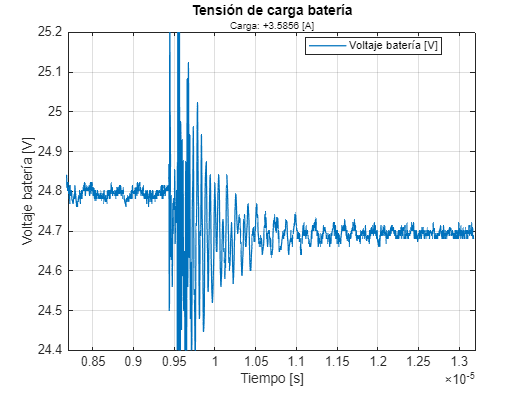

%Inputs
data = ["scope_25.csv", "scope_19.csv"];
labels1 = {"Tiempo [s]", "Voltaje batería [V]", "Tensión de relajación batería", "Carga: -3.5856 [A]"};
labels2 = {"Tiempo [s]", "Voltaje batería [V]", "Tensión de carga batería", "Carga: +3.5856 [A]"};
labels = {labels1, labels2};


limits1 = [-2e-6,8e-6 , 22,22.8 , NaN,NaN]; %NaN por axis for auto 
limits2 = [8.2e-6,1.32e-5  , 24.4,25.2 , NaN,NaN]; %NaN por axis for auto 
limits = {limits1,limits2};

outputName = ["bat_11.png","bat_33.png"];

%Fun Fcall
for i = 1:2
    plot_scope_data(data(i), labels{i}, limits{i}, outputName(i));
end

% data = readmatrix("scope_25.csv", 'NumHeaderLines', 2);
% 
% time = data(:, 1);
% signal1 = data(:, 2);
% 
% mean(signal1(1:350)) - mean(signal1(1500:1999))


# Tdff

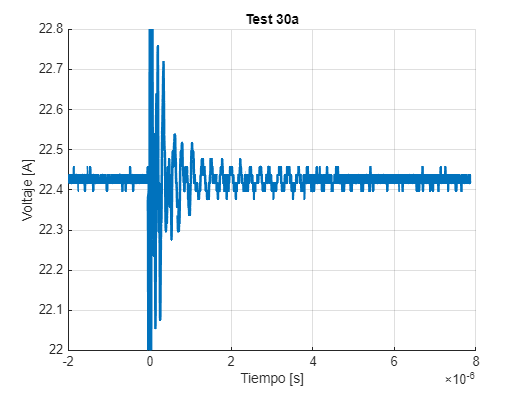

rSense = 1.5e-3;

data = readmatrix("scope_25.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
% current_1      = data(:, 3);
% current_1      = current_1 / rSense; %Rsense corriente

clf %% clean figure

figure(3)
hold on 
grid on
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
ylim([22,22.8]);
ylabel("Voltaje [A]");

xlabel("Tiempo [s]");
xlim([-2e-6  8e-6])
title("Test 30a");
% subtitle(plotSubTitle,'FontSize',8);
hold off


% exportgraphics(gcf,"bat_1.png");
% exportgraphics(gcf,"Figuras/inrush_switch.png");

current_av = mean(volt_1(1:350))

current_av = 22.4248

mean(volt_1(1300:1999))

ans = 22.4240